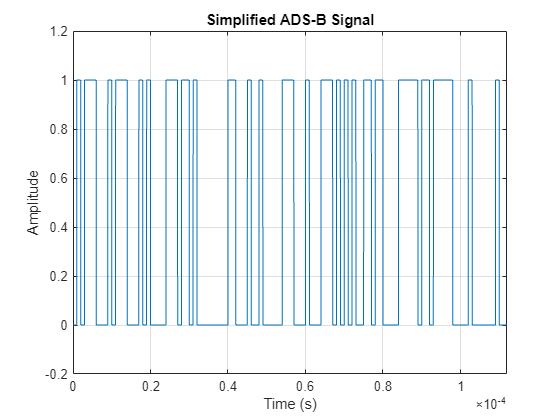

% MATLAB Script to Generate and Plot a Simplified ADS-B Signal

% Step 1: Define a binary message (simply a random binary vector for demonstration)
message = randi([0 1], 1, 112);  % Typical ADS-B messages are 112 bits
% Step 2: Encode the message
% In a real ADS-B, encoding would involve error correction - we will skip this here
encoded_message = message;  % Placeholder for simplicity

% Step 3: Modulate the Signal
% We will use a simple Pulse Position Modulation (PPM) - not exactly as in ADS-B
fs = 1e6;  % Sampling frequency (1 MHz for illustration)
sample_per_bit = 100;  % Number of samples per bit
t = linspace(0, length(encoded_message)/fs, length(encoded_message)*sample_per_bit);
signal = zeros(1, length(t));

% Fill the signal array where we place a pulse for each '1'
for i = 1:length(encoded_message)
    if encoded_message(i) == 1
        signal((i-1)*sample_per_bit + 1:i*sample_per_bit) = 1;
    end
end

% Step 4: Plot the Signal
figure;
plot(t, signal);
title('Simplified ADS-B Signal');
xlabel('Time (s)');
ylabel('Amplitude');
axis([0 max(t) -0.2 1.2]);
grid on;

% MATLAB Script to Generate and Plot PPM ADS-B Signal from "<text>"

% Step 1: Convert "<text>" to binary
text = 'H';
binaryMessage = reshape(dec2bin(text, 8).' - '0', 1, [])

binaryMessage =      0     1     0     0     1     0     0     0


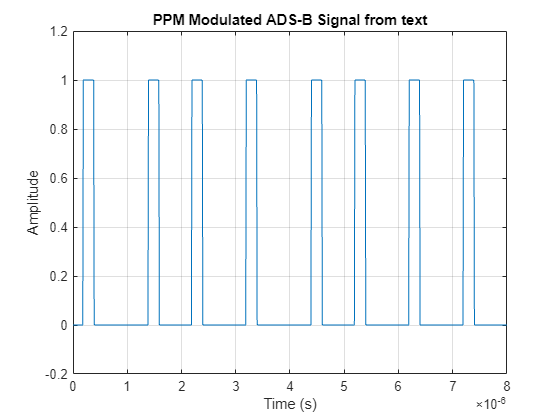

% Step 2: PPM Modulate the Signal
fs = 1e6;  % Sampling frequency (1 MHz for illustration)
sample_per_bit = 100;  % Number of samples per bit
pulse_width = 20;  % Width of each pulse in samples
num_bits = length(binaryMessage);
t = linspace(0, num_bits/fs, num_bits*sample_per_bit);
signal = zeros(1, length(t));

% PPM Modulation: Different positions for '0' and '1'
for i = 1:num_bits
    if binaryMessage(i) == 1
        start_index = (i-1)*sample_per_bit + sample_per_bit/2 - pulse_width/2;
        signal(start_index:start_index + pulse_width - 1) = 1;
    else
        start_index = (i-1)*sample_per_bit + pulse_width;
        signal(start_index:start_index + pulse_width - 1) = 1;
    end
end

% Step 3: Plot the Signal
figure;
plot(t, signal);
title('PPM Modulated ADS-B Signal from text');
xlabel('Time (s)');
ylabel('Amplitude');
axis([0 max(t) -0.2 1.2]);
grid on;

% MATLAB Script to Generate ADS-B Signal with Message Structure

% Define ADS-B Message
icao_address = '8D4068'; % Example ICAO addressin Hex
text_message = 'A'; % Text message to be transmitted

% Convert Text to Binary
binary_message = dec2bin(text_message, 8); % Convert text message to binary

% Convert ICAO Address to Binary
icao_binary = hexToBinaryVector(icao_address);

% Construct ADS-B Signal
fs = 1e6; % Sampling frequency (1 MHz for illustration)
bit_duration = 1/fs; % Duration of one bit

% Preamble: Alternating 0s and 1s
preamble = repmat([0 1], 1, 8)

preamble =      0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1


% DF (Downlink Format) bits
df_binary = dec2bin(hex2dec('17'), 5) - '0' % Downlink Format (DF) bits for ADS-B

df_binary =      1     0     1     1     1


% CA (Capability) bits
ca_binary = dec2bin(hex2dec('0'), 3) - '0' % Capability (CA) bits (set to 0 for now)

ca_binary =      0     0     0


% Data
signal = [preamble df_binary ca_binary icao_binary] % Start of signal

signal =      0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     1     0     1     1     1     0     0     0     1     0     0     0     1     1     0     1     0     1     0     0     0     0     0     0     0     1     1     0     1     0     0     0


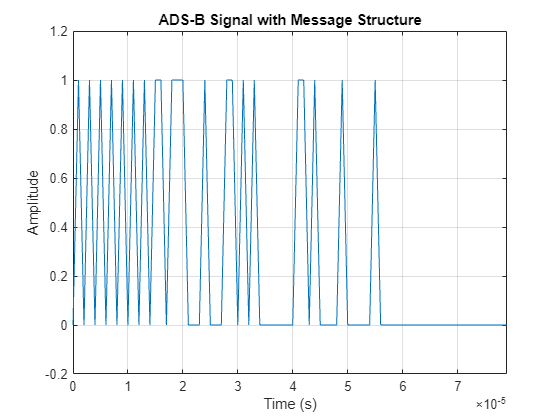

% Add Text Message
for i = 1:length(text_message)
    char_binary = binary_message(i, :) - '0'; % Binary representation of current character
    signal = [signal char_binary]; % Append character binary to signal
end

% Parity/Interrogator ID (PI) bits (filling with zeros for now)
pi_binary = zeros(1, 24);
signal = [signal pi_binary]; % Append PI bits

% Step 5: Plot the Signal
t = (0:length(signal)-1) * bit_duration;
figure;
plot(t, signal);
title('ADS-B Signal with Message Structure');
xlabel('Time (s)');
ylabel('Amplitude');
axis([0 max(t) -0.2 1.2]);
grid on;